% # This code can be used to extract the sheet resistance of
% conductive films (e.g., conductive fabric, MXene, etc.).
% # This code needs two-port microstrip transmission line 
% S-parameters in the form of .s2p files (dB/angle degrees). 
% # The following parameters need to be edited into the main.mlx
% file: 1. filename: Name of the .s2p file from the network analyzer,
% 2. CL: connector loss in dB (optional, default 0), 3. dl: connector 
% length (meters), from the point of calibration to the device under 
% test (DUT)/transmission line top, 4. ub, lb: upper and lower bound of
% optimization, doesn't need to change, 5. m: number of the frequency
% of interest in the freq vector. The sheet resistance value is calculated
% at this frequency, 6. len: length of the transmission line / DUT in meters,
% 7. w: width of top layer in meters, 8. rad_eff: radiation efficiency (%)
% of the transmission line, typically less than 5% for electrically small
% transmission lines. Can be derived from simulation.

clc, clear all, close all;
filename = 'sample1_41mm.s2p'; % S2P file from network analyzer 
data = dlmread(filename,'',9,0);
data = data(1:100:end/4, :); %reducing the number of data points (optional)
n=length(data);
CL = 0; %connector loss (dB)
data(:,4) = data(:,4) + CL.*ones(n, 1); %connector loss adjustment

freq =1e-9.*data(:,1);
n=length(data);
% dl = 0.43 / 100; %connector length in m;
dl = 0.6 / 100; %connector length in m;

ub = [10, 0]; %lower bound of W,d,e1,e2
lb = [-5, -2];
store = zeros(n,5,7);

RG = zeros(7,2);

R_store = zeros(1,7); %stores the 7-day Rs data at 900MHz
S21_store = zeros(1,7);

[Ro, Lo, Co, Go,gamma, gamma_t, Z0L,s11,s21,s11r,s21r,z_opt] =...
    RLCG_func(data, ub, lb,dl);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



imag(z_opt(1));

store(:,1,1) = real(gamma);
store(:,2,1) = Ro;
store(:,3,1) = Lo;
store(:,4,1) = Co;
store(:,5,1) = Go;
store(:,6,1) = s21;
S21_store(1) = 20*log10(abs(store(5,6,1)));


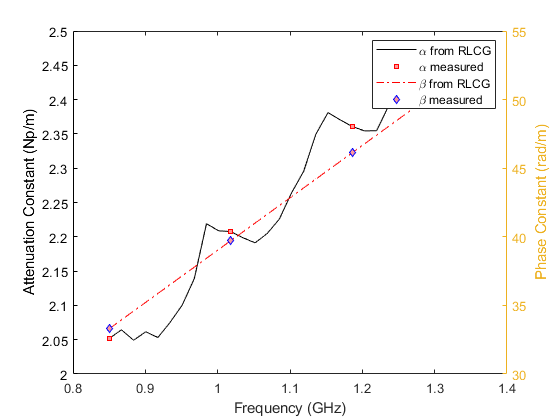

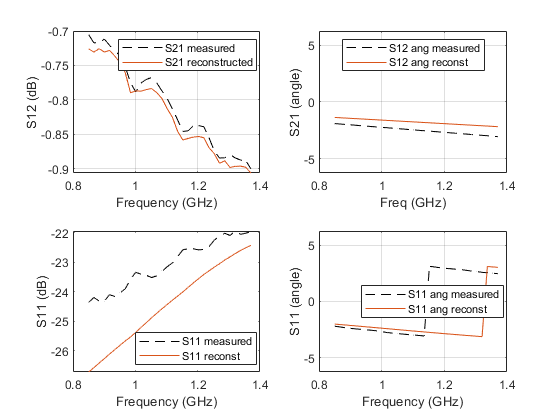

plot_SG(freq,gamma, gamma_t,  s11r, s21r, s11, s21);

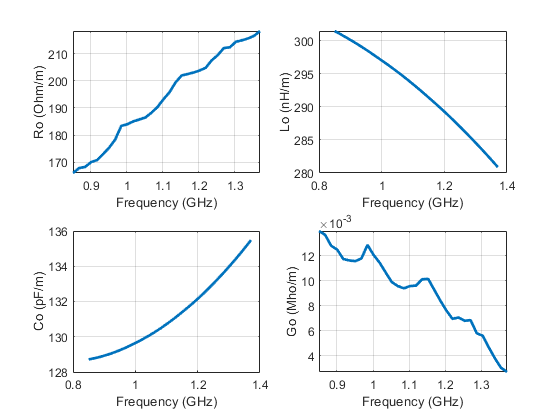


figure
subplot(2,2,1)
% Ro = movmean(Ro, 50);
plot(freq, Ro,'linewidth',2);
ylabel('Ro (Ohm/m)'), xlabel('Frequency (GHz)');
grid on;
axis tight;

subplot(2,2,2)
plot(freq, Lo,'linewidth',2);
ylabel('Lo (nH/m)'), xlabel('Frequency (GHz)');
grid on;
% axis([0.5,3,0,500]);


subplot(2,2,3)
plot(freq, (10^3)*Co,'linewidth',2);
ylabel('Co (pF/m)'), xlabel('Frequency (GHz)');
grid on;
% axis([0.5,3,20,100]);

subplot(2,2,4)
% Go = movmean(Go, 50);
plot(freq, Go,'linewidth',2);
ylabel('Go (Mho/m)'), xlabel('Frequency (GHz)');
grid on;
axis tight;

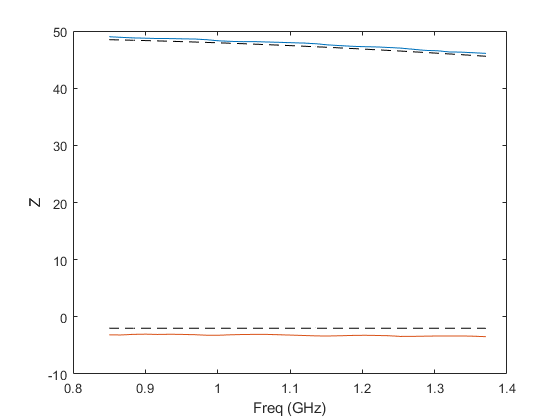


figure
plot(freq, real(Z0L));
hold on;
plot(freq, imag(Z0L));
hold on;
plot(freq, real(z_opt),'k--');
hold on;
plot(freq, imag(z_opt),'k--');
hold on;
xlabel('Freq (GHz)'), ylabel('Z');

%Sheet Resistance Calculation
m = 4; % 4th element in the freq vector indicates 900 MHz
len = 41/1000; % transmission line length in meters
w = 3/1000; % top layer width in meters
rad_eff = 4/100; % Radiation efficiency (%) of transmission line
skin_depth = sqrt(1.678e-8./(pi.*freq(m).*1e9.*0.999991.*4.*pi.*1e-7)) %skin...

skin_depth = 2.1725e-06

%depth (m) of copper at freq(m) GHz

R_total = len * Ro(m)

R_total = 6.9733

R_rad = rad_eff*R_total

R_rad = 0.2789

R_gnd = 1.678e-8*(len/(3*w*skin_depth)) % Resistance (Ohm) of the ground layer copper

R_gnd = 0.0352

R_top = R_total - R_gnd - R_rad % Resistance (Ohm) of the top layer conductor

R_top = 6.6591

Rs = R_top * (w/len) % RF Sheet resistance (Ohm/sq) of the top layer conductor

Rs = 0.4873